clear;
clc; close all

windowWidth = 10;

path = cd;
testNum = 2;
fileList = dir(fullfile(path,'*.mat'));
fileName = fileList(testNum).name;
expData = load([path '\' fileName]);
myData = expData.data.data;

fileList = dir(fullfile(path,'*.txt'));
logData = importdata(fileList(testNum).name);
logTime = (logData(:,1) - logData(1,1))*1e-3;

logHePres = movmean(logData(:,3),windowWidth)/10*0;
logLoxPres = logData(:,2)/10;
valve1State = logData(:,end);
valve2State = logData(:,end-1)*2;

if testNum == 1
    timeDiff = -(9.429-7.338);
    flowTimes = [54.68 84.54];
else
    timeDiff = -(42.07-39.55);
    flowTimes = [103.5, 145.9];
end
logTime = logTime-timeDiff;

presTime = myData{1,3} - myData{1,3}(1);

for i = 4:8
    pressArr (i-3,:) = movmean(myData{1,i},windowWidth);
end
pressArr (6,:) = movmean(myData{1,11},windowWidth);

regIn = pressArr(1,:);
smallOrif = pressArr(2,:);
bigOrif = pressArr(3,:);
regOut = pressArr(4,:);
loxTank = pressArr(5,:);
sourceTank = pressArr(6,:);
% pressArr = [movmean(regIn,windowWidth); movmean(smallOrif,windowWidth); movmean(bigOrif, windowWidth); movmean(regOut,windowWidth); movmean(loxTank,windowWidth)];
movMeanDeneme = movmean([bigOrif; regOut],windowWidth);
legendArr = ["Reg In", "Small Orifice","Big Orifice","Reg Out","LOX Tank", "Source Tank"];
presInds = [1,6];

sourceTemp = myData{1,14};
loxTemp = myData{1,15};
tempTime = myData{1,13}-myData{1,13}(1);

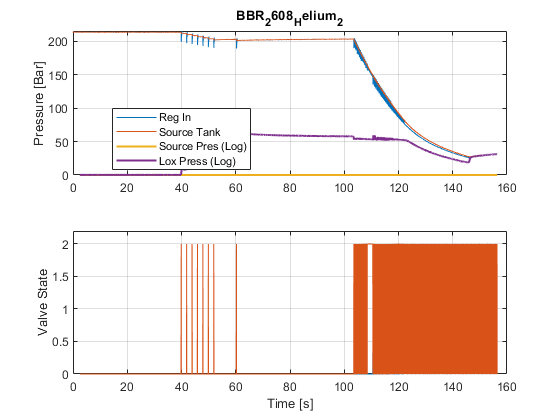

f = figure(1);
presPlot = subplot(2,1,1);
plot(presTime, pressArr(presInds,:),'-');
grid on; ylim([0 inf]); hold on
plot(logTime,[logHePres logLoxPres],'linewidth',1.5)
title(fileName(1:end-4))
ylabel('Pressure [Bar]');
legend([legendArr(presInds) "Source Pres (Log)" "Lox Press (Log)"],'location','best')
%xlim(flowTimes)
valvePlot = subplot(2,1,2);
plot(logTime,[valve1State valve2State])
hold on; grid on
ylabel('Valve State'); xlabel('Time [s]')
ylim([0 2.2]); %xlim(flowTimes)
linkaxes([presPlot valvePlot],'x')

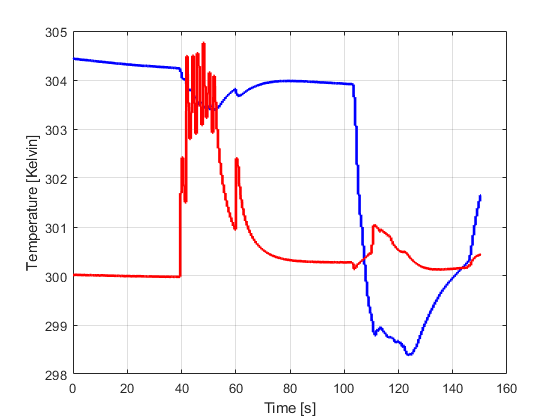

figure(2)
plot(tempTime,sourceTemp,'b',tempTime,loxTemp,'r','linewidth',2)
grid on; hold on;
%xlim(flowTimes)
ylabel('Temperature [Kelvin]'); xlabel('Time [s]')
if exist('modelSource') && exist('modelLOX')
    plot(modelSourceTemp.time+flowTimes(1), modelSourceTemp.signals.values,'b--','linewidth',2)
    plot(modelLOXTemp.time+flowTimes(1), modelLOXTemp.signals.values,'r--','linewidth',2)
    legend('Source Temperature', 'LOX Temperature','Model Source', 'Model LOX')
end
hold off

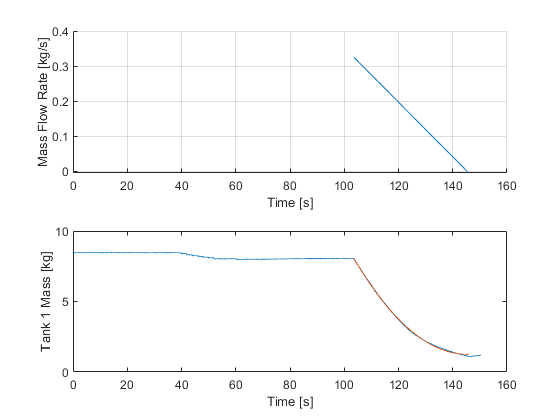

myLen = length(sourceTank);
vTank = 250e-3;
R = 2077.1;
dt = 0.01;
mTank1 = zeros(myLen,1);
for i = 1:myLen
    t = presTime(i);
    indT = find(tempTime>=t,1);
    if isempty(indT)
        indT = length(tempTime);
    end
    T1 = round(sourceTemp(indT));
    P1 = round(sourceTank(i));
    mTank1(i) = (P1*1e5) * vTank / (R*T1);
end

figure(3)
flowInds = find(presTime>flowTimes(1),1):find(presTime>flowTimes(2),1);
massFlowPlot = subplot(2,1,1);
P = polyfit(presTime(flowInds), mTank1(flowInds),2);
xTime = flowTimes(1):0.01:flowTimes(2);
yMass = polyval(P,xTime);
hold on
plot(xTime,-polyval(polyder(P),xTime))
grid on; xlabel('Time [s]'); ylabel('Mass Flow Rate [kg/s]')
fontSize = 15;
hold off
tankMassPlot = subplot(2,1,2);
plot(presTime,movmean(mTank1,25),xTime,yMass);
ylabel('Tank 1 Mass [kg]');
xlabel('Time [s]')
linkaxes([massFlowPlot tankMassPlot],'x')

%xlim(flowTimes)

## Simulink Comparison

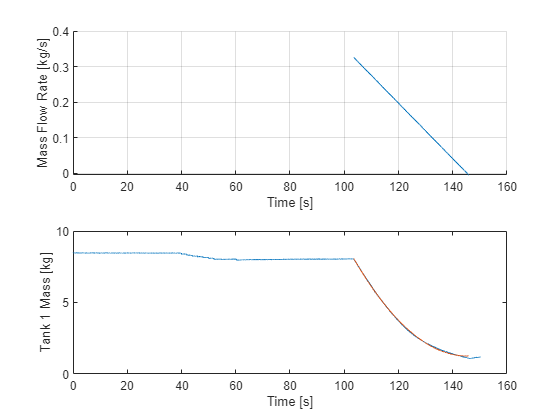

if exist('modelSource') && exist('modelLOX')
    logFlowInds = find(logTime>flowTimes(1),1):find(logTime>flowTimes(2),1);
    figure(4)
    plot(logTime(logFlowInds),logLoxPres(logFlowInds),'b',modelLOX.time+flowTimes(1),modelLOX.signals.values,'k--','Linewidth',2)
    hold on;
    plot(presTime(flowInds),sourceTank(flowInds),'r',modelSource.time+flowTimes(1),modelSource.signals.values,'r--','Linewidth',2)
    legend('Experiment LOX','Model LOX','Experiment Source','Model Source')
    ylabel('Pressure [Bar]'); xlabel('Time [sec]'); grid on
end
hold off